Projet Tutoré Académique

# Simulation d'une Machine Assynchone à double alimentation

# et son controle de facteur de puissance donée au réseau

ENSEM 3A - Bureau d'énergie 

09/02/24

Étudiant : SALES Déric 

clc; clear all; close all;

% Changer le dossier actuel pour l'endroit où se trouve le fichier MATLAB actuel
if(~isdeployed)
    path = fileparts(matlab.desktop.editor.getActiveFilename);
  cd(path);
end

## Paramètres phisiques de la machine

Lfs = 360e-6;
Lfr = 180e-6;
Lm = 12e-3;
Ls = Lfs + Lm;
Lr = Lfr + Lm;

Msr = Lm;
%M = (3/2)*Msr; % Inductance mutuelle entre le stator et le rotor, en henrys
M = Msr;
Rr = 38e-3;  % Résistance du rotor, en ohms
Rs = 60e-3;  % Résistance du stator, en ohms
p = 2;  % Nombre de pôles du moteur


f = -22;  % coeficient de frottement
J = 0.4;  % moment d'inertie du rotor de la machine

g = 0.01; % glissement de la machine en pourcentage

taur = Lr/Rr; % constante de temps rotorique

Ps=1MW

Qs=200kVAR

réseau 600V rms (-sin(theta)) 50Hz

Descriptive plus detailée des variables:

- J $\rightarrow$ Moment d'inertie du rotor, en kg.m². C'est une mesure de la résistance du rotor au changement de vitesse de rotation.

- Ls $\rightarrow$ Inductance du stator, en henrys. Cela représente la capacité du stator à stocker de l'énergie sous forme de champ magnétique.

- Lr = Ls $\rightarrow$ Inductance du rotor, en henrys. On suppose ici que l'inductance du rotor est égale à celle du stator.

- M $\rightarrow$ Inductance mutuelle entre le stator et le rotor, en henrys. Ceci mesure l'efficacité du couplage magnétique entre le stator et le rotor.

- Rr $\rightarrow$ Résistance du rotor, en ohms. Cela représente les pertes électriques dans le rotor dues à sa résistance.

- Rs $\rightarrow$ Résistance du stator, en ohms. Similaire à Rr, mais pour le stator.

- p $\rightarrow$ Nombre de pôles du moteur. Cela affecte la vitesse de rotation synchrone du moteur.

- f $\rightarrow$ Coefficient de frottement. Cela représente les pertes mécaniques dues au frottement.

- R $\rightarrow$ Matrice de résistance avec des valeurs négatives pour la formulation des équations différentielles.

- ML $\rightarrow$ Matrice d'inductance incluant l'inductance propre et mutuelle.

## Controlêur

### Matrices de transformations

Transformation de Concordia-Park :

T_23 = sqrt(2/3)*[1 -1/2 -1/2;  0  sqrt(3)/2 -sqrt(3)/2];
T_32 = T_23';

### Calcul coefitients du controleur 

Vs = 600;

Leq = Lr - ((M^2)/Ls);
Req = Rr;

p1 = 1;
p2 = 1;

Kp = 1/(p1*Req)

Kp = 26.3158

%Ki = (p2*Req)/Leq
taui = p2*(Leq/Req)

taui = 0.0139

## Exécution de la simulation

Définition des paramètres de la simulation :

start_time = 0.0;
stop_time = 30.0;
fixed_step_size = 1e-4;

Execution de la simulation :

%sim('MADA2');

Effacer des variables dans l'espace de travail

% axe du temps
t = start_time:fixed_step_size:stop_time;

% List all variables in the base workspace
vars = evalin('base', 'who');

% Identify variables to keep
varsToKeep = {'ans', 't', 'path' };

% Identify variables to clear
varsToClear = setdiff(vars, varsToKeep);

% Clear the variables except for those in varsToKeep
clear(varsToClear{:});

clear vars varsToClear varsToKeep

## Récuperation des données de la simulation

% ficher pour souvegarder les images des simulaitons
clear saving_folder
saving_folder = 'simuImgs';
saving_folder = fullfile(path,saving_folder);

#### vitesse de rotation du rotor de la machine

wm = ans.wm;

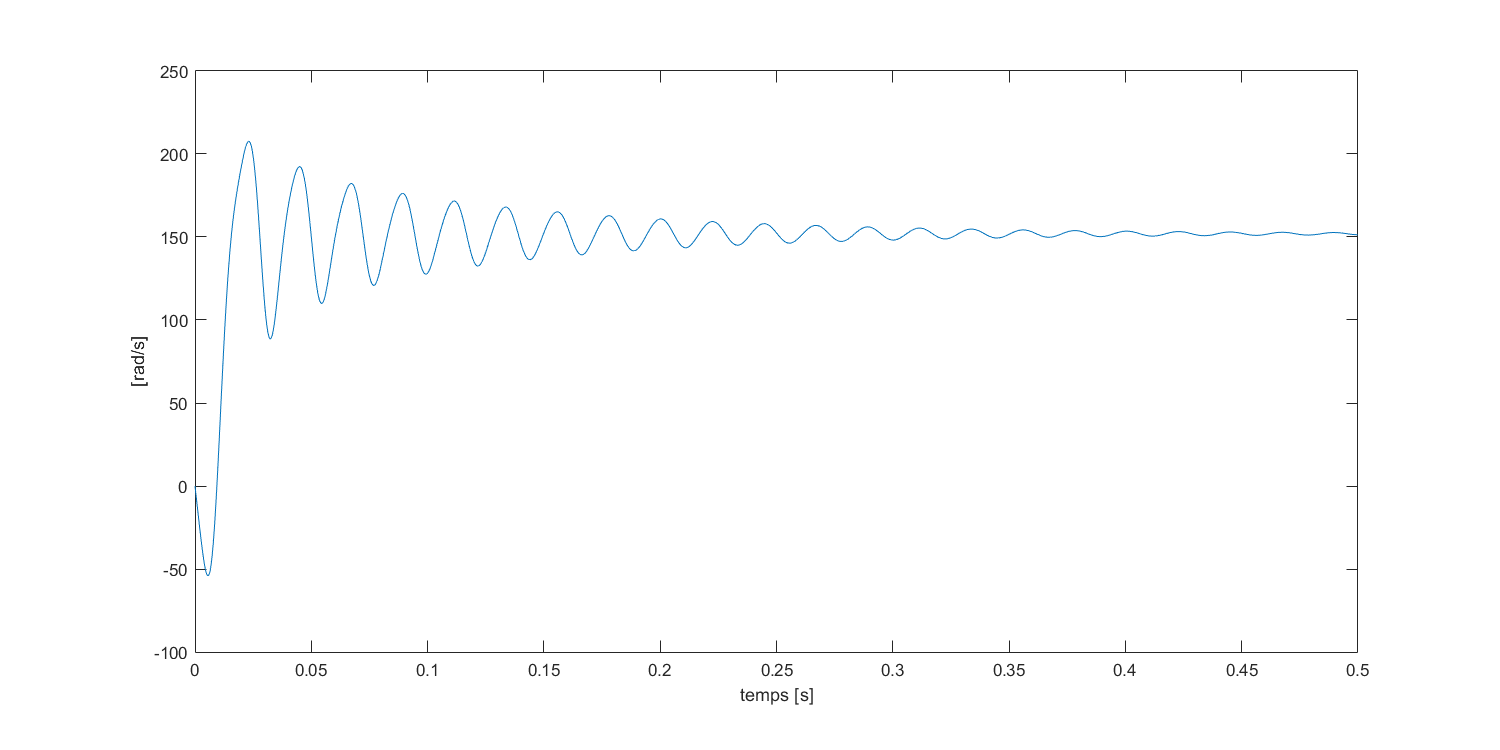

figure;
plot(t(1:1e4/2),wm(1:1e4/2)); 
xlabel("temps [s]");
ylabel("[rad/s]");

% ajuster les dimensions du graphe
figSize = [100, 100, 1200, 600]; % This makes the figure window 1200x600 pixels
set(gcf, 'Position', figSize); % Adjusts the size of the figure window
pbaspect([2 1 1]); % Makes the plot aspect ratio 2:1 width to height

% exporter la figure
figure_nom = fullfile(saving_folder, 'wm.png');
exportgraphics(gca, figure_nom, 'Resolution', 300); 

#### courant triphasées du stator

is_abc = ans.is_abc;

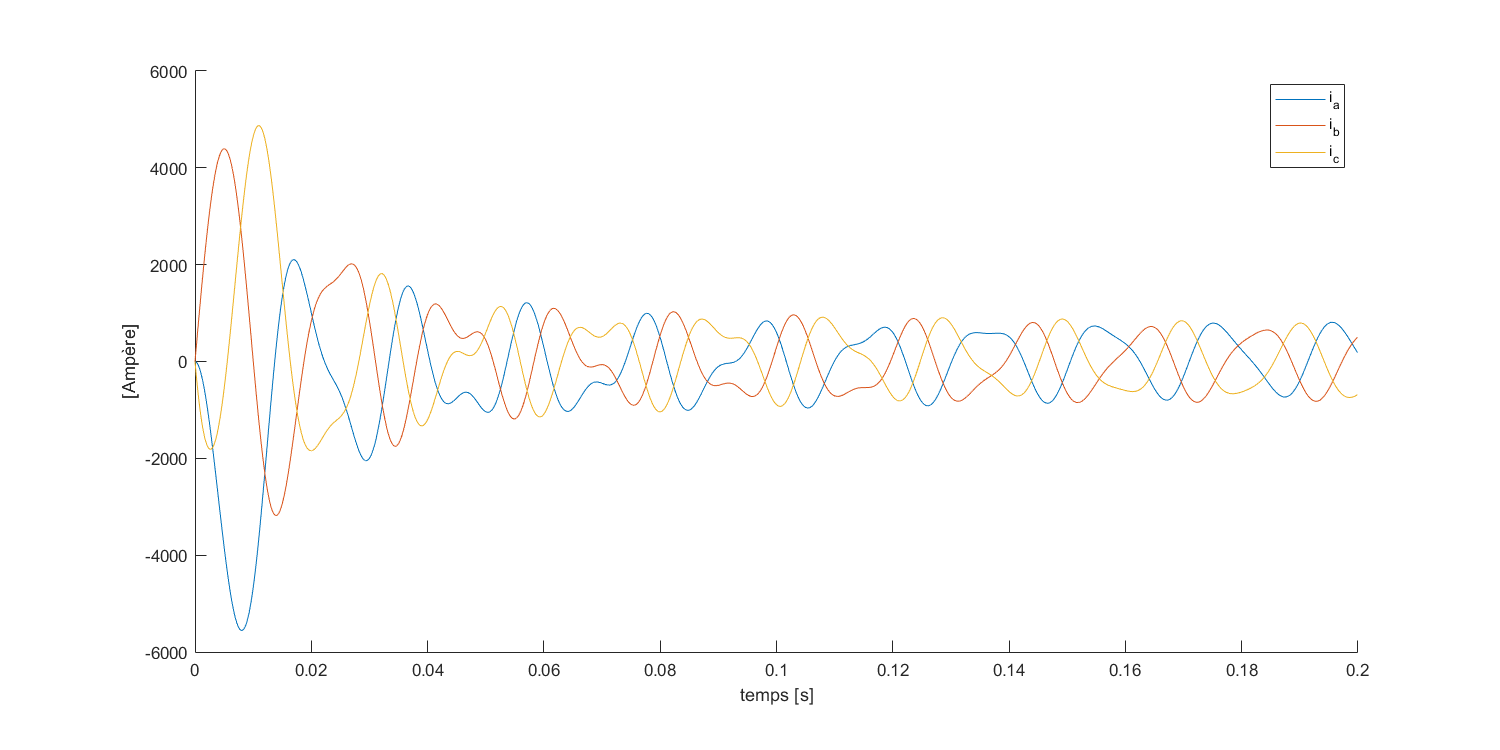

figure;
hold on;
plot(t(1:1e4/5),is_abc(1:1e4/5,1), 'DisplayName', 'i_a'); 
plot(t(1:1e4/5),is_abc(1:1e4/5,2), 'DisplayName', 'i_b'); 
plot(t(1:1e4/5),is_abc(1:1e4/5,3), 'DisplayName', 'i_c'); 
legend()
xlabel("temps [s]");
ylabel("[Ampère]");
hold off;

% ajuster les dimensions du graphe
figSize = [100, 100, 1200, 600]; % This makes the figure window 1200x600 pixels
set(gcf, 'Position', figSize); % Adjusts the size of the figure window
pbaspect([2 1 1]); % Makes the plot aspect ratio 2:1 width to height

% exporter la figure
figure_nom = fullfile(saving_folder, 'is_abc.png');
exportgraphics(gca, figure_nom, 'Resolution', 300); 

#### puissance de la machine 

P = ans.P;

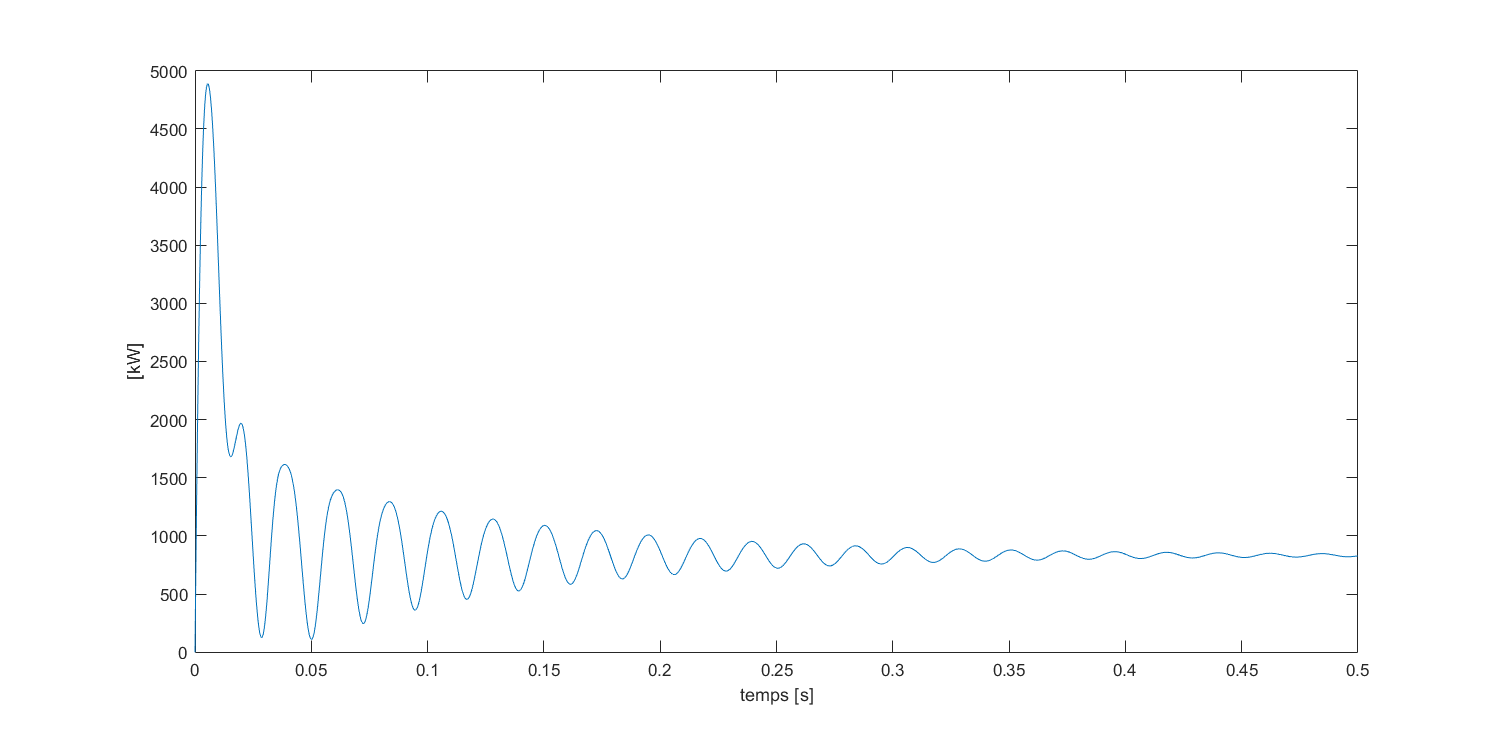

figure;
P = P/1e3;
plot(t(1:1e4/2),P(1:1e4/2)); 
xlabel("temps [s]");
ylabel("[kW]");

% ajuster les dimensions du graphe
figSize = [100, 100, 1200, 600]; 
set(gcf, 'Position', figSize); 
pbaspect([2 1 1]);

% exporter la figure
figure_nom = fullfile(saving_folder, 'P.png');
exportgraphics(gca, figure_nom, 'Resolution', 300); 

#### torque de la machine

torque = ans.torque;

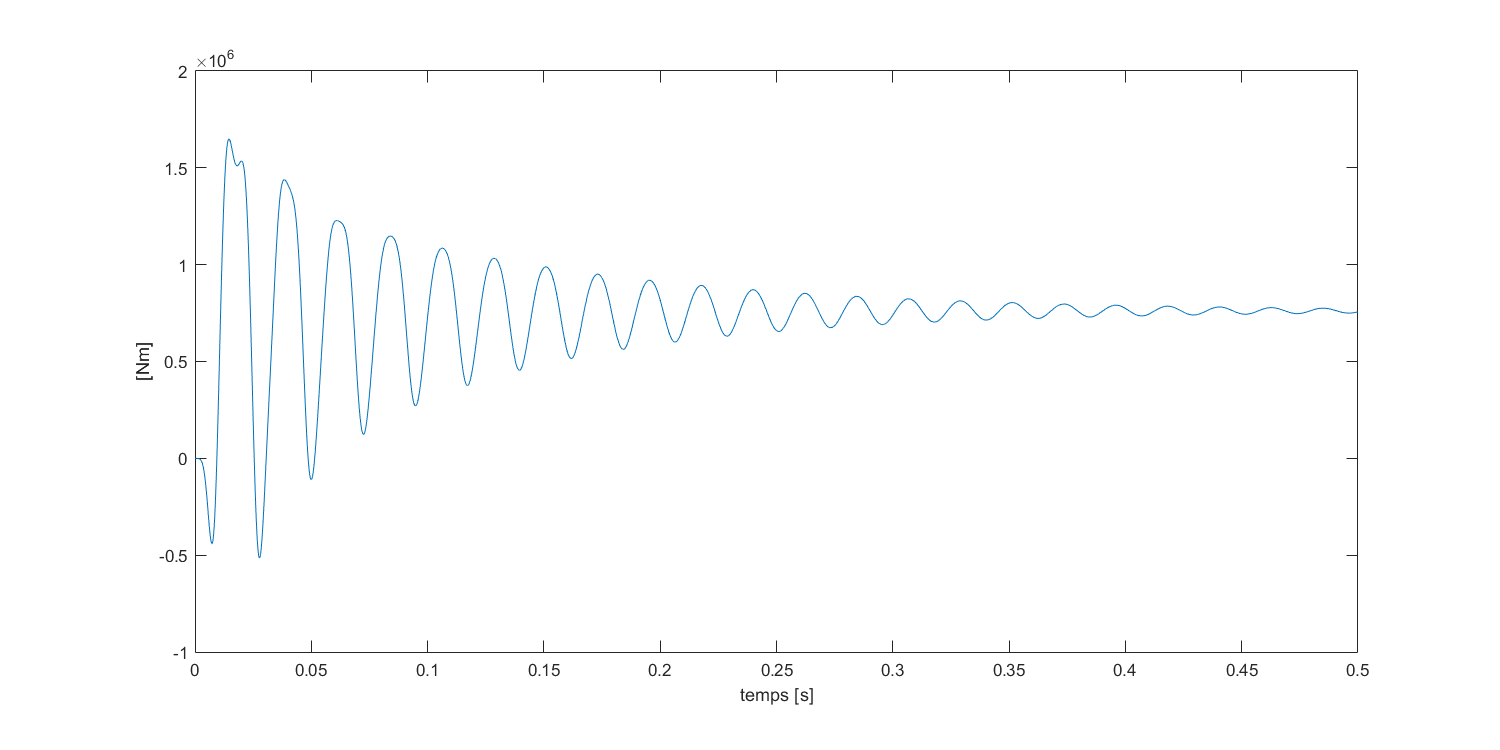

figure;
plot(t(1:1e4/2),torque(1:1e4/2)); 
xlabel("temps [s]");
ylabel("[Nm]");

% ajuster les dimensions du graphe
figSize = [100, 100, 1200, 600]; 
set(gcf, 'Position', figSize); 
pbaspect([2 1 1]);

% exporter la figure
figure_nom = fullfile(saving_folder, 'torque.png');
exportgraphics(gca, figure_nom, 'Resolution', 300); 

#### courrants triphasées du rotor

ir_abc = ans.ir_abc;

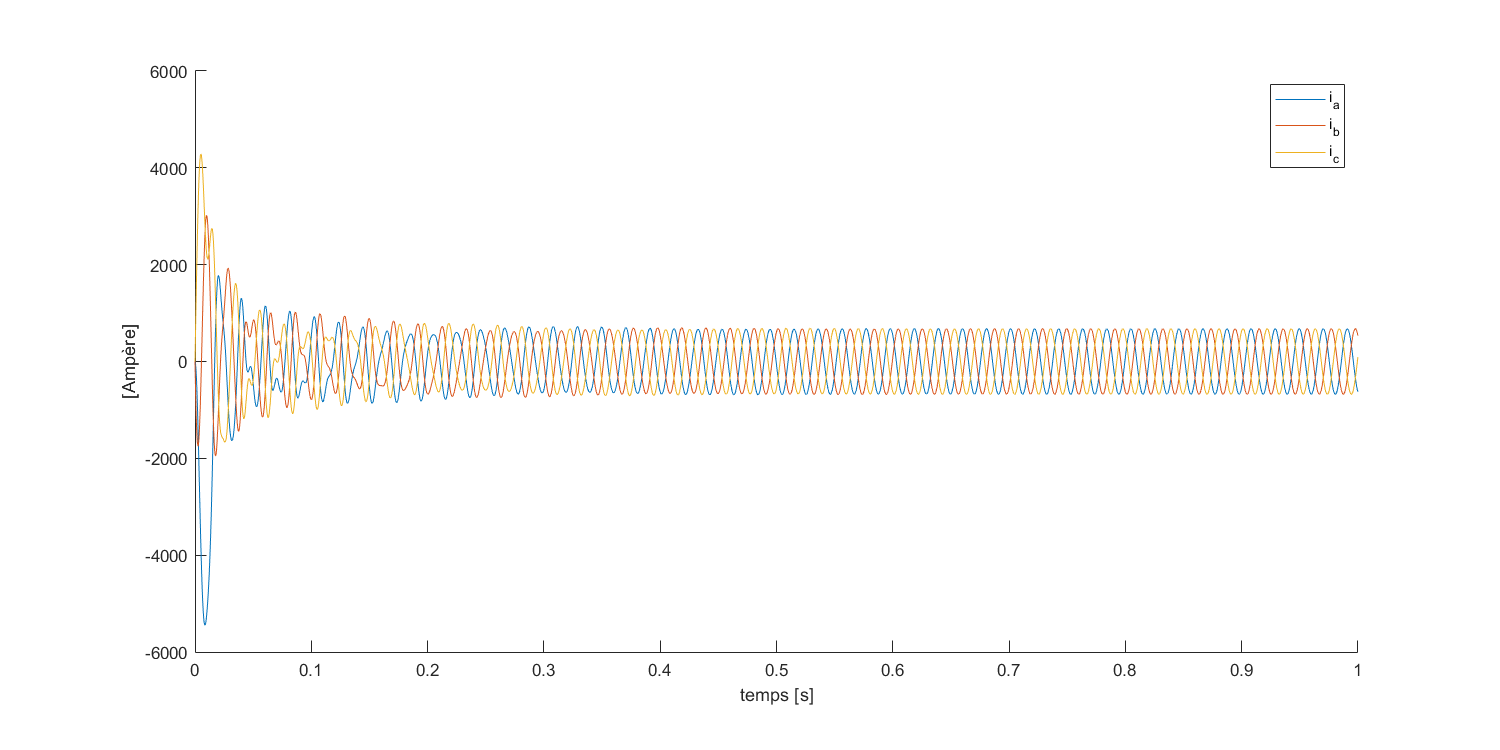

figure;
hold on;
plot(t(1:1e4),ir_abc(1:1e4,1), 'DisplayName', 'i_a'); 
plot(t(1:1e4),ir_abc(1:1e4,2), 'DisplayName', 'i_b'); 
plot(t(1:1e4),ir_abc(1:1e4,3), 'DisplayName', 'i_c'); 
legend();
xlabel("temps [s]");
ylabel("[Ampère]");
hold off;

% ajuster les dimensions du graphe
figSize = [100, 100, 1200, 600]; % This makes the figure window 1200x600 pixels
set(gcf, 'Position', figSize); % Adjusts the size of the figure window
pbaspect([2 1 1]); % Makes the plot aspect ratio 2:1 width to height

% exporter la figure
figure_nom = fullfile(saving_folder, 'ir_abc.png');
exportgraphics(gca, figure_nom, 'Resolution', 300); 

#### couple de la machine

Ce = ans.Ce;

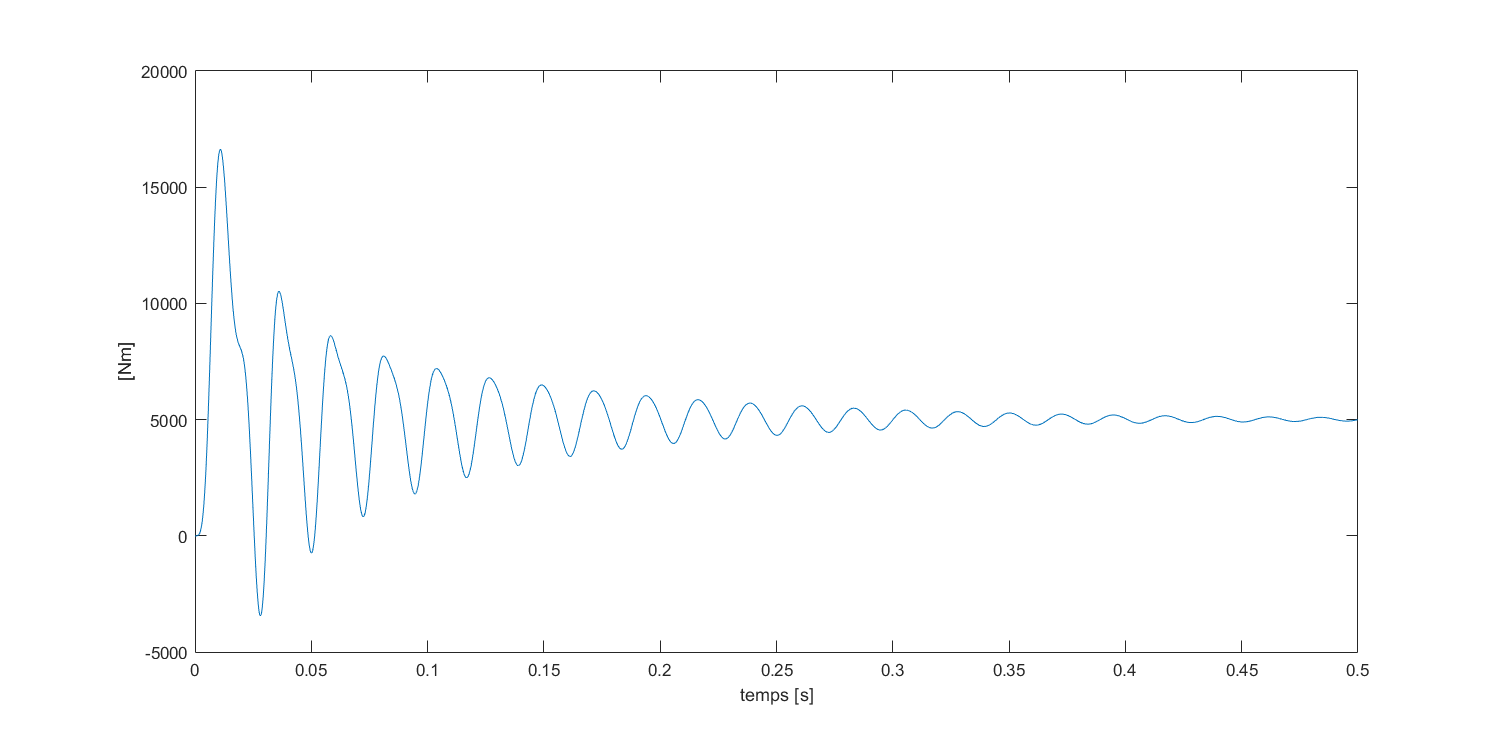

figure;
plot(t(1:1e4/2),Ce(1:1e4/2)); 
xlabel("temps [s]");
ylabel("[Nm]");

% ajuster les dimensions du graphe
figSize = [100, 100, 1200, 600]; 
set(gcf, 'Position', figSize); 
pbaspect([2 1 1]);

% exporter la figure
figure_nom = fullfile(saving_folder, 'Ce.png');
exportgraphics(gca, figure_nom, 'Resolution', 300); 

#### tensions abc du stator

vs_abc = ans.vs_abc;

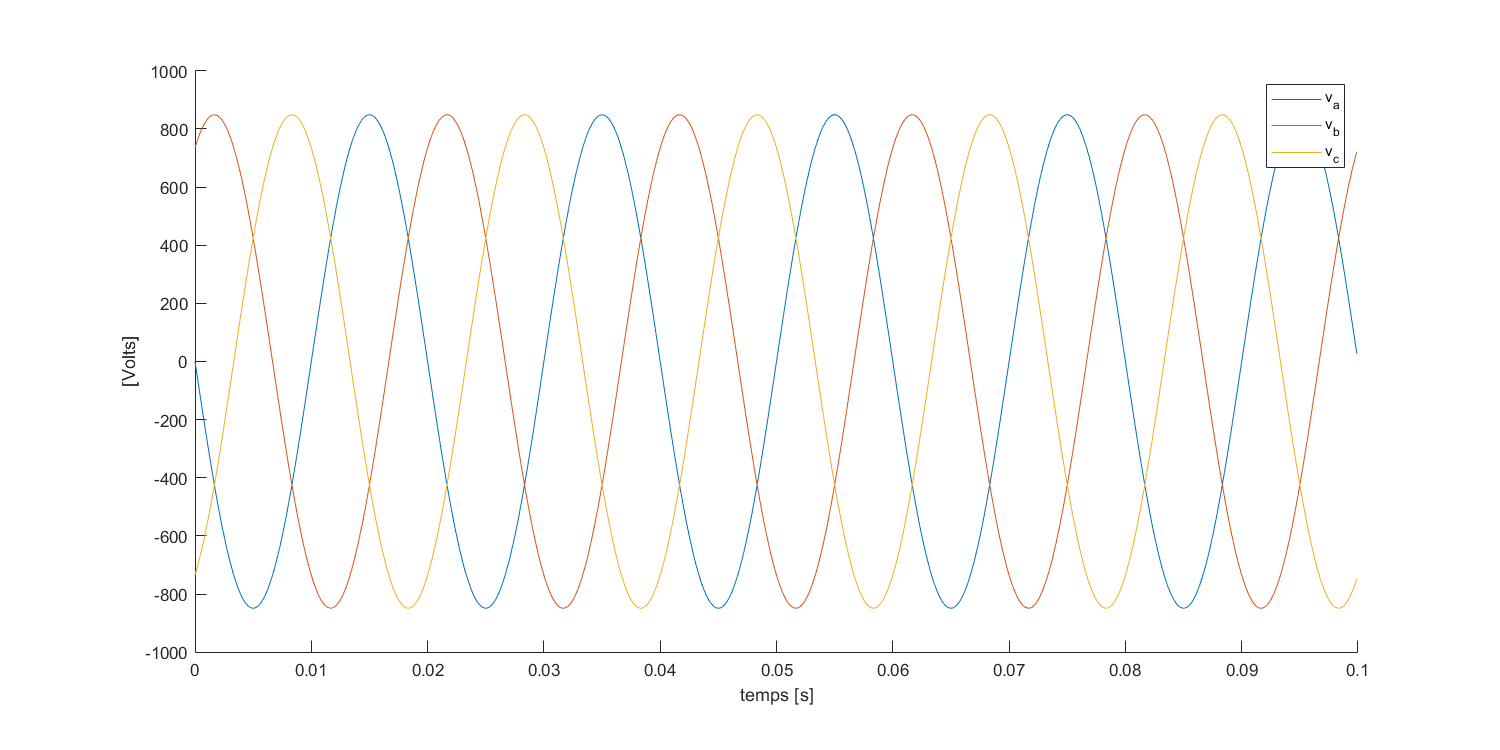

figure;
hold on;
plot(t(1:1e4/10),vs_abc(1:1e4/10,1), 'DisplayName', 'v_a'); 
plot(t(1:1e4/10),vs_abc(1:1e4/10,2), 'DisplayName', 'v_b'); 
plot(t(1:1e4/10),vs_abc(1:1e4/10,3), 'DisplayName', 'v_c'); 
legend();
xlabel("temps [s]");
ylabel("[Volts]");
hold off;

% ajuster les dimensions du graphe
figSize = [100, 100, 1200, 600]; % This makes the figure window 1200x600 pixels
set(gcf, 'Position', figSize); % Adjusts the size of the figure window
pbaspect([2 1 1]); % Makes the plot aspect ratio 2:1 width to height

% exporter la figure
figure_nom = fullfile(saving_folder, 'vs_abc.png');
exportgraphics(gca, figure_nom, 'Resolution', 300); 

#### tensions dq du rotor

% vr_dq = ans.vr_dq;

% figure;
% hold on;
% plot(t(1:1e4/2),vr_dq(1:1e4/2,1), 'DisplayName', 'v_d'); 
% plot(t(1:1e4/2),vr_dq(1:1e4/2,2), 'DisplayName', 'v_q'); 
% legend();
% xlabel("temps [s]");
% ylabel("[Volts]");
% hold off;
% 
% % ajuster les dimensions du graphe
% figSize = [100, 100, 1200, 600]; % This makes the figure window 1200x600 pixels
% set(gcf, 'Position', figSize); % Adjusts the size of the figure window
% pbaspect([2 1 1]); % Makes the plot aspect ratio 2:1 width to height
% 
% % exporter la figure
% figure_nom = fullfile(saving_folder, 'vr_dq.png');
% exportgraphics(gca, figure_nom, 'Resolution', 300); 

#### tensions dq du stator

vs_dq = ans.vs_dq;

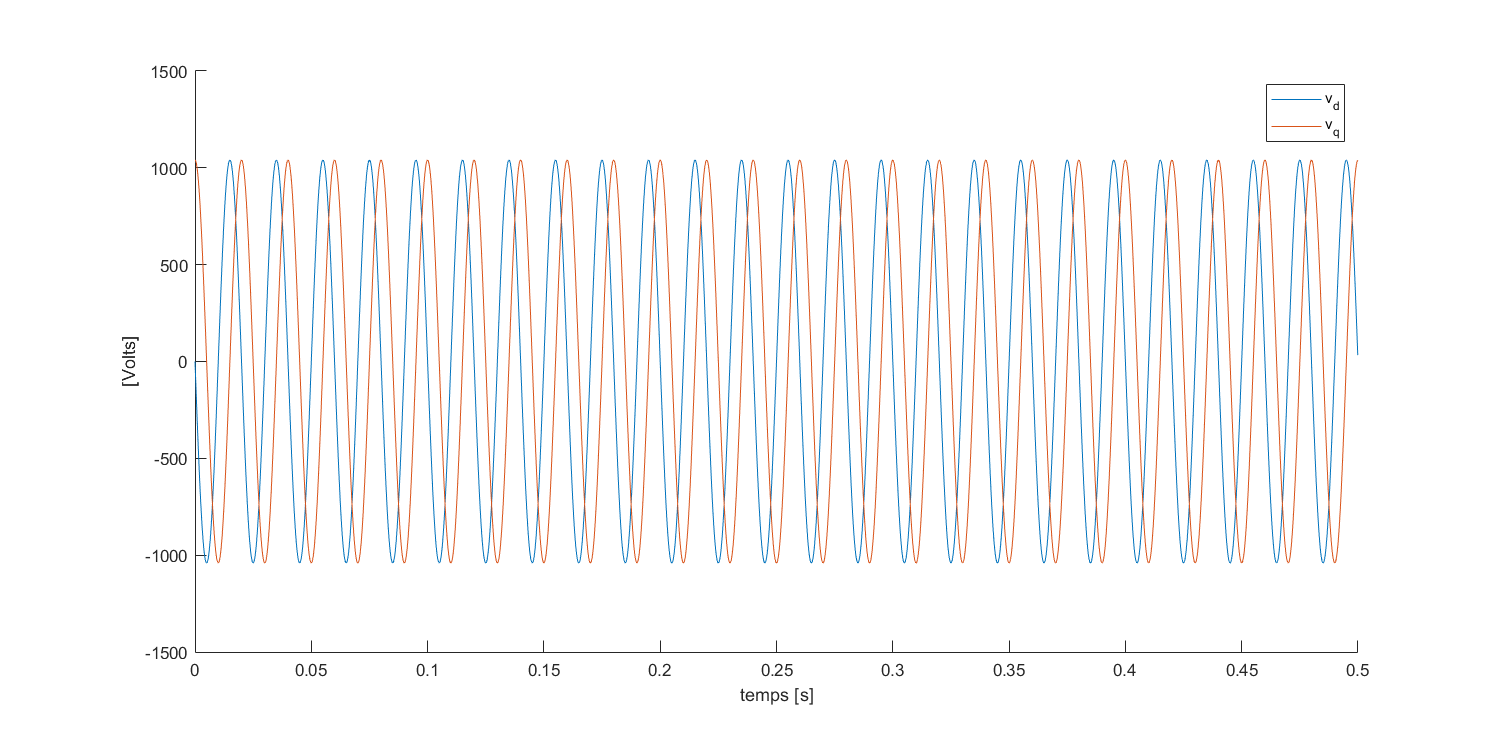

figure;
hold on;
plot(t(1:1e4/2),vs_dq(1:1e4/2,1), 'DisplayName', 'v_d'); 
plot(t(1:1e4/2),vs_dq(1:1e4/2,2), 'DisplayName', 'v_q'); 
legend();
xlabel("temps [s]");
ylabel("[Volts]");
hold off;

% ajuster les dimensions du graphe
figSize = [100, 100, 1200, 600]; % This makes the figure window 1200x600 pixels
set(gcf, 'Position', figSize); % Adjusts the size of the figure window
pbaspect([2 1 1]); % Makes the plot aspect ratio 2:1 width to height

% exporter la figure
figure_nom = fullfile(saving_folder, 'vs_dq.png');
exportgraphics(gca, figure_nom, 'Resolution', 300); 

#### courants alpha beta du rotor

ir_alphabeta = ans.ir_alphabeta;

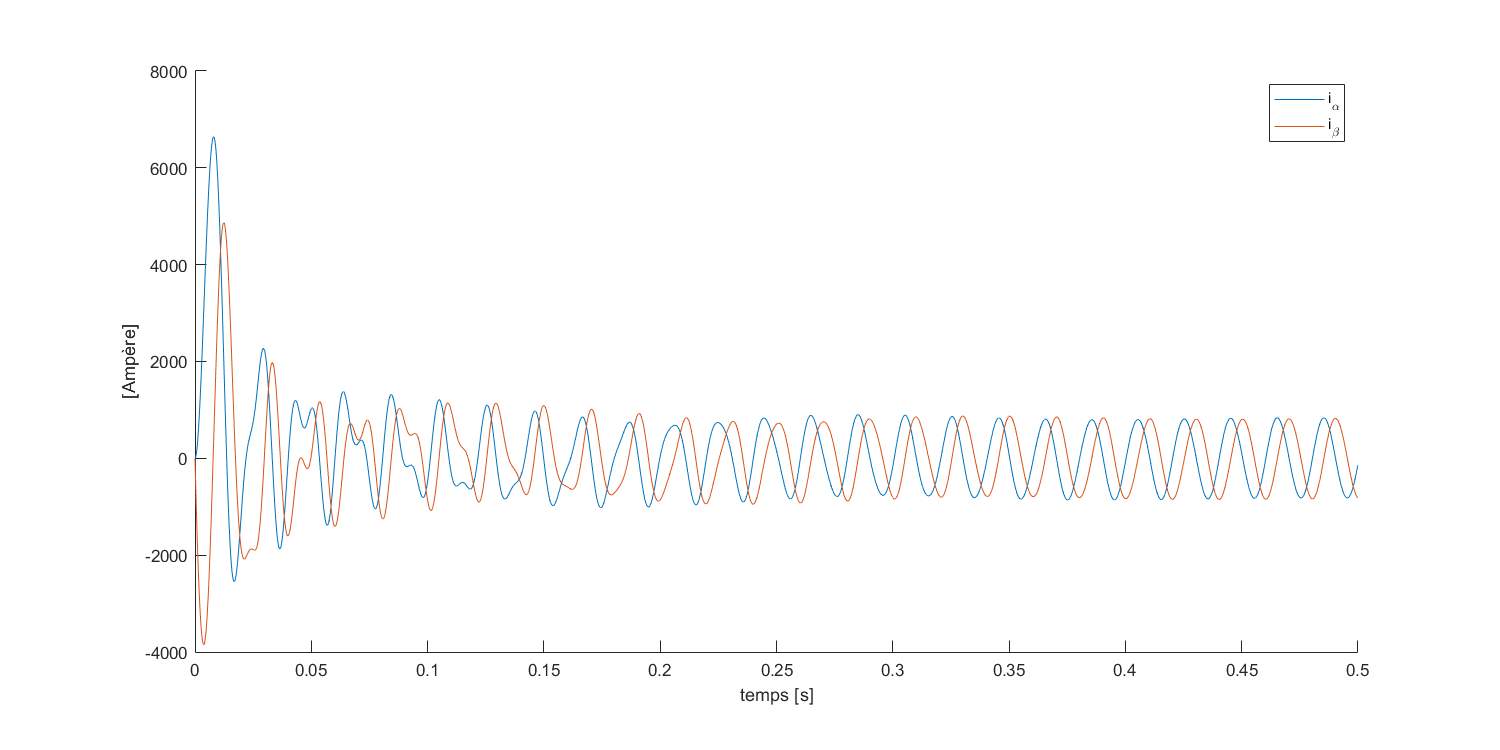

figure;
hold on;
plot(t(1:1e4/2),ir_alphabeta(1:1e4/2,1), 'DisplayName', 'i_\alpha'); 
plot(t(1:1e4/2),ir_alphabeta(1:1e4/2,2), 'DisplayName', 'i_\beta'); 
legend();
xlabel("temps [s]");
ylabel("[Ampère]");
hold off;

% ajuster les dimensions du graphe
figSize = [100, 100, 1200, 600]; % This makes the figure window 1200x600 pixels
set(gcf, 'Position', figSize); % Adjusts the size of the figure window
pbaspect([2 1 1]); % Makes the plot aspect ratio 2:1 width to height

% exporter la figure
figure_nom = fullfile(saving_folder, 'ir_alphabeta.png');
exportgraphics(gca, figure_nom, 'Resolution', 300);

#### tensions controlées par le controlateur

vs_dq = ans.vs_dq;

figure;
hold on;
plot(t(1:1e4/2),vs_dq(1:1e4/2,1), 'DisplayName', 'v_d'); 
plot(t(1:1e4/2),vs_dq(1:1e4/2,2), 'DisplayName', 'v_q'); 
legend();
xlabel("temps [s]");
ylabel("[Volts]");
hold off;

% ajuster les dimensions du graphe
figSize = [100, 100, 1200, 600]; % This makes the figure window 1200x600 pixels
set(gcf, 'Position', figSize); % Adjusts the size of the figure window
pbaspect([2 1 1]); % Makes the plot aspect ratio 2:1 width to height

% exporter la figure
figure_nom = fullfile(saving_folder, 'vs_dq.png');
exportgraphics(gca, figure_nom, 'Resolution', 300);

#### fluxes du rotor

fluxes  = ans.fluxes ;

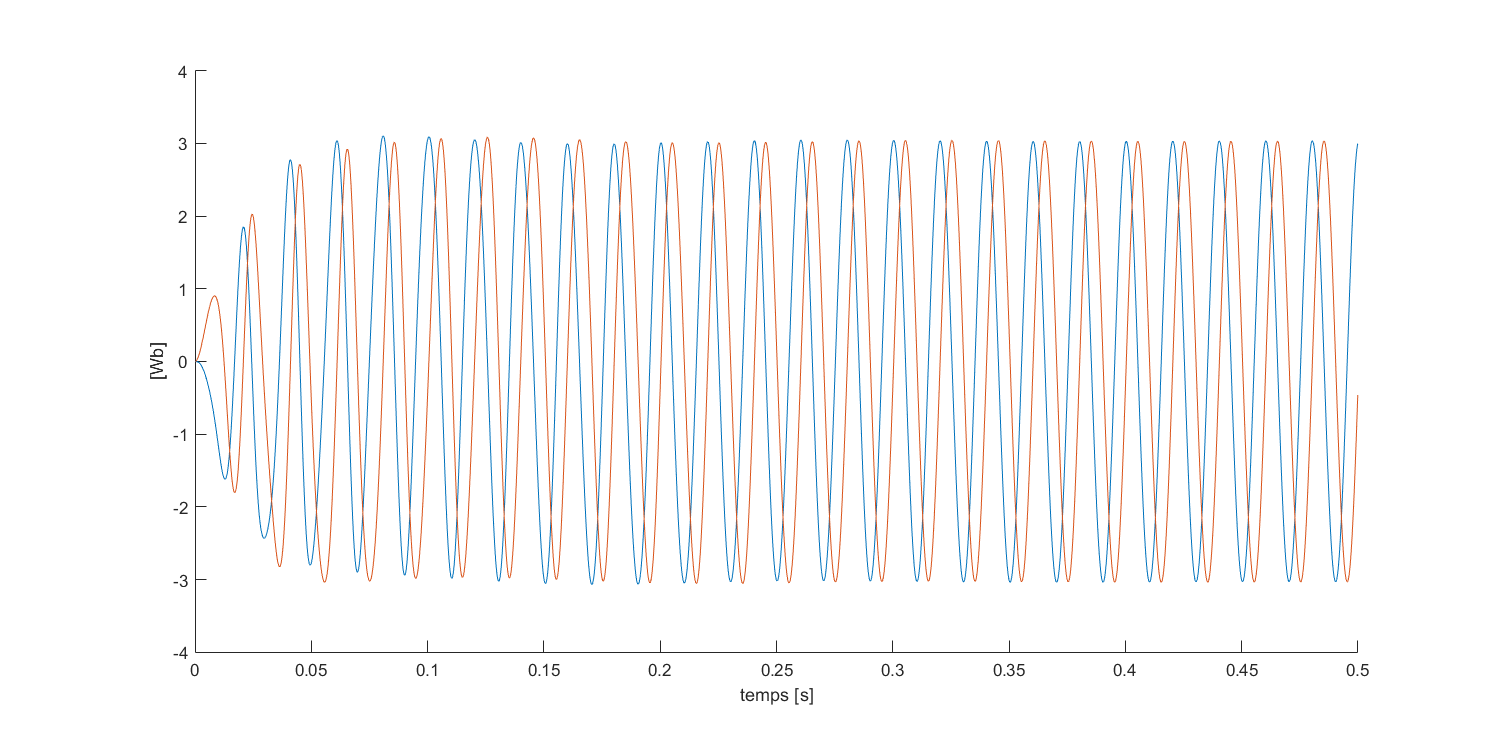

figure;
hold on
plot(t(1:1e4/2),fluxes (1:1e4/2,1), 'DisplayName', '\varphi_{dr}'); 
plot(t(1:1e4/2),fluxes (1:1e4/2,2), 'DisplayName', '\varphi_{qr}'); 
xlabel("temps [s]");
ylabel("[Wb]");
hold off

% ajuster les dimensions du graphe
figSize = [100, 100, 1200, 600]; 
set(gcf, 'Position', figSize); 
pbaspect([2 1 1]);

% exporter la figure
figure_nom = fullfile(saving_folder, 'fluxes .png');
exportgraphics(gca, figure_nom, 'Resolution', 300); 